% 20230526 测试了异质性对网络的影响
% PING
% 根据目前使用的参数，可以分为以下几类：微分方程求解基本参数（tspan）
% 电刺激参数（elecStimulus_py elecStimulus_in elecStimulusMatrix）
% 光刺激参数（optoStimulus optoStimulusMatrix irradiance）
% 网络连接参数（ConnectMatrix synapticMatrix n pMatrix）
% 噪声参数（noiseValue(6,1)）


%% ING
% 根据目前使用的参数，可以分为以下几类：微分方程求解基本参数（tspan）
% 电刺激参数（elecStimulus_in elecStimulusMatrix）
% 光刺激参数（optoStimulus optoStimulusMatrix irradiance）
% 网络连接参数（ConnectMatrix n ）
% 噪声参数（noiseValue(6,1)）

% 振荡的参数敏感性，呈现出显著的动力学分岔
% 影响ING的参数维度：
% 
% 1. 在方程network中
% 1.1 beta_gaba，GABA突触的开启函数中的decay时间常数
% 1.2 line 155, I_ChR2(i)=-(O1(i)+gama*O2(i))*G_rectify(v_soma(i))*1.5, 后面这个1.5, ChR2单位面积上的电导密度（暂未定义）
% 1.3 g_in_in，突触连接强度
% 1.4 line 66, Ielectrical(i)=elecStimulusMatrix(i)*elecStimulus_in(ceil(t/0.1)+1)-v_soma(i)*sstoch_temp(ceil(t/0.1)+1)*0.12, 后面这个系数0.12（暂未定义）
% 
% 2. 在测试主程序中
% 2.1 ConnectMatrix中的各项参数，注意，通常我们关注的是稀疏连接条件下的同步性
% 2.2 电刺激的波形、幅度
% 2.3 光刺激的波形、光强

% 还未证实的一些影响参数：
% (1) 共振频率还和网络的规模有关。
% (2) 由于分岔特性，存在网络的"最低共振频率"，该最低共振频率应该是可以根据突触连接强度来调节的。
% (3) 


clear

% load large_suqsireal_network.mat
% load small_suqsireal_network.mat
global T_MAX step 
T_MAX             = 10000;
step              = 0.1;
tspan             = 0:step:T_MAX; 

% 新增参数组：compartment geometry and dimensions
Soma_area  = 12.56;  % um^2, assuming a 1um radius sphere
Soma_volume= 4.19;   % um^3, assuming a 1um radius sphere



## 网络参数设定（连接矩阵）

% n             = 100;             % 网络中的神经元数量
% 
% ConnectMatrix = zeros(n,n);      % 网络连接矩阵
% ConnectMatrix1= ConnectMatrix;   % 按方式1生成的，无标度随机网络
% ConnectMatrix2= ConnectMatrix;   % 按方式2生成的，小世界随机网络
% ConnectMatrix3= ConnectMatrix;   % 按方式3生成的，个别设定的网络
% 
% 
% % 方式一：随机网络（scale-free），p为连接概率
% probability                   = 0.4;    % 连接概率
% ConnectMatrix1                = binornd(1,probability,n,n);
% 
% % 方式二：小世界网络+随机网络，通过函数NWnetwork
% probability                   = 0.05;   % 连接概率
% MN_adjp                       = 2;   % 邻近点个数
% ConnectMatrix2                = NWnetwork(n,MN_adjp,probability);
% 
% % 方式三：单独设定神经元之间的连接
% 
% ConnectMatrix3(60,10) = 1;
% ConnectMatrix3(60,15) = 1;
% ConnectMatrix3(60,20) = 1; 
% % ConnectMatrix3(10,20) = 1; 
% % ConnectMatrix3(20,10) = 1; 
% % for receiveord = 52:2:90
% %     ConnectMatrix3(2:2:40,receiveord) = 1; 
% % end
% % for receiveord = 2:2:40
% %     ConnectMatrix3(52:2:90,receiveord) = 1; 
% % end
% % for receiveord = 52:2:90
% %     ConnectMatrix3(52:2:90,receiveord) = 1; 
% % end
% % for receiveord = 2:2:40
% %     ConnectMatrix3(2:2:40,receiveord) = 1; 
% % end
% 
% % 最终使用网络为三种网络之一
% ConnectMatrix = ConnectMatrix3;
% % ConnectMatrix = zeros(n,n);
% 
% % 取消网络的自连接
% for i = 1 : n
%     ConnectMatrix(i,i) = 0;
% end
% 
% pcolor(ConnectMatrix);      % 绘制网络连接图（二维伪彩图） 
% colorbar
% 
% totalconnectionnumber  = sum(sum(ConnectMatrix))  % 连接的数量

% n                     =  787;             % 网络中的神经元数量
% n                     = 900;
n                     = 200;
type_of_neuron        =  ones(n,1);        % 神经元类型，默认为椎体神经元

% interneuron_index     =  1:491; 
% interneuron_index     =  1:450;
interneuron_index     =  1:100;
pyramid_index         =  interneuron_index(end)+1:n; 

type_of_neuron(interneuron_index) =  2;                % 定义中间神经元

% 连接矩阵（abstract network = 10cells, 2 interneurons, 8 pyramids）


ConnectMatrix         =  []; 
ConnectMatrix         =  [ConnectMatrix;1,2,22];

% eeConnection          =  nchoosek(1:10,2); 
% iiConnection          =  nchoosek(interneuron_index,2); 
% iiConnectNum          =  randperm(nchoosek(interneuron_index(end),2),nchoosek(interneuron_index(end),2)*0.6); 
% inter_eeConnectNum    =  randperm(nchoosek(interneuron_index(end),2),nchoosek(interneuron_index(end),2)*0.2); 
% 
% for i = iiConnectNum
    % ConnectMatrix     =  [ConnectMatrix;iiConnection(i,1),iiConnection(i,2),22]; 
    % ConnectMatrix     =  [ConnectMatrix;iiConnection(i,2),iiConnection(i,1),22]; 
% end
% 
% % i:e = 1:10, 1 group consisting 1 icell and 10 ecell
% for i = interneuron_index
%     for j = 1:10   % inner-group ie and ei connections
%         ConnectMatrix     =  [ConnectMatrix;i,interneuron_index(end)+10*(i-1)+j,21]; 
%         ConnectMatrix     =  [ConnectMatrix;interneuron_index(end)+10*(i-1)+j,i,12]; 
%     end
%     eeConnectNum          =  randperm(nchoosek(10,2),15);  % inner-group ee connections
%     for k = 1:15  
%         ecell1            =  eeConnection(eeConnectNum(k),1);
%         ecell2            =  eeConnection(eeConnectNum(k),2);
%         ConnectMatrix     =  [ConnectMatrix;interneuron_index(end)+10*(i-1)+ecell1,interneuron_index(end)+10*(i-1)+ecell2,11]; 
%         ConnectMatrix     =  [ConnectMatrix;interneuron_index(end)+10*(i-1)+ecell2,interneuron_index(end)+10*(i-1)+ecell1,11]; 
%     end
% end
% 
% for i = 1:length(inter_eeConnectNum)
%     icell1                =  iiConnection(inter_eeConnectNum(i),1); 
%     icell2                =  iiConnection(inter_eeConnectNum(i),2); 
%     ecell1                =  interneuron_index(end)+10*(icell1-1)+randperm(10,1);
%     ecell2                =  interneuron_index(end)+10*(icell2-1)+randperm(10,1);
%     ConnectMatrix         =  [ConnectMatrix;ecell1,ecell2,11]; 
%     ConnectMatrix         =  [ConnectMatrix;ecell2,ecell1,11]; 
% end

% ConnectMatrix             =  [];




% % construct interneuron reciprocal connections
% ConnectMatrix         =  [70,80,22]; 
% ConnectMatrix         =  [ConnectMatrix;80,70,22]; 
% ConnectMatrix         =  [ConnectMatrix;50,60,22]; 
% ConnectMatrix         =  [ConnectMatrix;60,50,22]; 

% % construct a e-e hopfield 
% eeHopf_grp            =  200:10:250; 
% eeHopf_indx           =  nchoosek(eeHopf_grp,2); 
% for i = 1:length(eeHopf_indx)
%     pymd1 = eeHopf_indx(i,1);
%     pymd2 = eeHopf_indx(i,2);
%     ConnectMatrix         =  [ConnectMatrix;pymd1,pymd2,11];
%     ConnectMatrix         =  [ConnectMatrix;pymd2,pymd1,11];
% end

% % construct inter-pyrmd reciprocal connections
% ConnectMatrix         =  [ConnectMatrix;70,200,21];      % 120 have random electric input
% ConnectMatrix         =  [ConnectMatrix;200,70,12]; 
% 
% ConnectMatrix         =  [ConnectMatrix;80,260,21];      % 130 have random electric input
% ConnectMatrix         =  [ConnectMatrix;260,80,12]; 

% % group 1
% for i = 1:4
%     ConnectMatrix         =  [ConnectMatrix;70,pyramid_index_grp12(i),21];
%     ConnectMatrix         =  [ConnectMatrix;pyramid_index_grp12(i),70,12];
% end
% 
% % group 2
% for i = 5:8
%     ConnectMatrix         =  [ConnectMatrix;80,pyramid_index_grp12(i),21];
%     ConnectMatrix         =  [ConnectMatrix;pyramid_index_grp12(i),80,12];
% end




## 电刺激参数设定

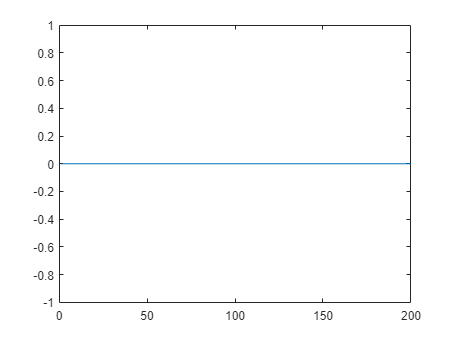

%% 1、电刺激背景
part                          = 1;                               % 加入刺激的比例（可变参数）

% continuous electrical stimulation without connections: LUT---------------
% Continuous_amp (constant A*random quantity)
% The constant A 所能引起的神经元放电频率 
% 0.15    - 约17Hz
% 0.14    - 约14Hz 
% 0.13    - 约10Hz
% 0.125   - 约7-8Hz
% 0.122   - 约5Hz
% 0.12    - 约2-3Hz
%--------------------------------------------------------------------------

% Current                       = 0.1.*rand(n,1)+0.1;                   % 电刺激强度（等效刺激电流，单位？）
% elecStimulus_in               = Current.*ones(length(tspan),1);       % 连续波背景刺激（等效刺激电流，单位？）。
elecStimulus_in               = 0.1.*rand(n,1)+0.1;                     % 连续波背景刺激（等效刺激电流，单位？）。

% 设定神经元上的电刺激矩阵
% 全部电刺激
elecStimulusMatrix(1:part*n)  = 0;  

% 部分电刺激（随机）
% elec_excited_cell_num       = 16;                                   % 随机加电刺激的个数
% cell_ord                    = randperm(n,elec_excited_cell_num)';   % 随机加电刺激的神经元序号
% for j = 1:elec_excited_cell_num
%     elecStimulusMatrix(cell_ord(j)) = 1;
% end

% 部分电刺激（个别设定）
elecStimulusMatrix(pyramid_index)  = 0;
% elecStimulusMatrix(240)  = 1;
% elecStimulusMatrix(40) = 1;
% elecStimulusMatrix(0.8*n+1:n)=1; 

% elecStimulusMatrix(1:part*n)  = 0;             % 无电刺激背景

figure;
plot(elecStimulus_in.*elecStimulusMatrix');


%% 2、模拟随机突触输入
% tau_d               = 3;           
% step                = 0.1;
% frequency           = 8;                      % Hz
% p                   = step*frequency/1000;
% t_temp              = 0;
% sstoch              = zeros(length(tspan),n);
% A                   = zeros(length(tspan),n);
% sstoch_amp          = 0.1;

% % 设定神经元上的突触输入矩阵
% elecSstochMatrix    = zeros(n,1); 
% 
% for k = pyramid_index                 % 部分神经元上加载了模拟突触输入
%     % k      = 120;
%     % k2     = 40;
%     t_temp = 0;  
%     for i = 1:length(tspan)
%         A(i) = binornd(1,p);
%         if A(i) == 0
%         sstoch(i,k) = exp(-(1/tau_d)*(i-1-t_temp)/10);
%         elseif A(i) == 1
%         sstoch(i,k) = sstoch_amp;
%         t_temp = i-1; % 记录对应时刻, i-1/10
%         end
%     end
%     % figure;
%     % plot(tspan,sstoch(:,k));
% end    
%     % sstoch(:,k2) = sstoch(:,k);

% sstoch      = zeros(length(tspan),n);         % 无模拟突触
sstoch      = [];                               % 无模拟突触

%% 3、设定电刺激中的高斯随机噪声
noiseValue  = 0;                                % 无按高斯分布形电噪声


## 光刺激参数设定

irradiance                      = zeros(n,1);                 % light intensitity (mW/mm^2) = (nW/um^2)

% 光刺激序列
% 经过测试，很难找到像5mW/mm2，10/50ms，20Hz脉冲序列这样，能实现1个光脉冲 = 1个spiking的一组理想参数（已解，方程函数中新增电导密度参数）
sDelay                          = 0;                  % 光刺激起始时间，default 200
sStart                          = 0;                  % 光刺激序列开始时间，Opto-stimulus start time (ms) default 200
sEnd                            = T_MAX;              % 光刺激序列结束时间，Opto-stimulus end time (ms) default 800
pWidth                          = 1000;                % 光刺激脉宽pulse width (ms) - if there is no optical stimulation, make pWidth to 0
pPeriod                         = 1000;                  % 光刺激序列周期pulse period (ms)
numPulses                       = (sEnd-sStart)/pPeriod;                % 光刺激序列的数量number of stimulus pulses

Optofrequency                   = 1000/pPeriod

Optofrequency = 1

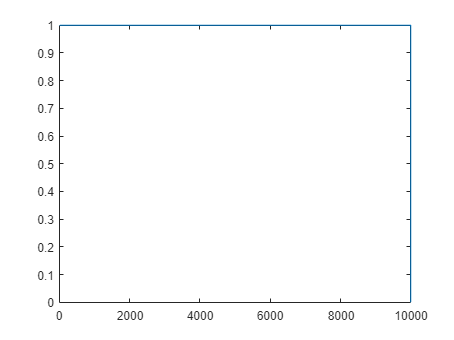


% Create an optical pulse train
optoStimulus(1:length(tspan))   = 0;
repetition(1:pPeriod/step)      = 0;
repetition(1:pWidth/step)       = 1;

for i = 1:numPulses 
    startPoint = (sDelay/step) + ((i-1) * (pPeriod/step)); 
    optoStimulus(startPoint+1:startPoint+length(repetition)) = repetition(1:length(repetition));
end

% optoStimulus1                   = optoStimulus';
optoStimulus_in                 = optoStimulus';    
figure;
plot(tspan,optoStimulus_in);                           % 由此生成光刺激波形，绘制光刺激波形图


% 新增参数组：表达水平
Molar_density                   = 1;                                                % ChR的摩尔浓度，1M = 1mol/L = 6.02x10^23/0.001m^3 = 6.02x10^8/um^3
Expression_density              = 6.02*10^8*Molar_density*Soma_volume/Soma_area;    % ChR2的表达水平，um^-2
g_ChR2                          = 1e-4;                                             % Conductance density of single ChR2 channel, mS/um^2

% 设定神经元上的光刺激矩阵
optoStimulusMatrix              = zeros(n,1);          % 光刺激矩阵
% 全部光刺激
% optoStimulusMatrix(1:part*n)  = 1;
% optoStimulusMatrix(1:round(part*n*0.8))  = 1;               % 序号为1-20的前1/5神经元上加载了20Hz光刺激
% optoStimulusMatrix(interneuron_index)  = 1; 
% irradiance_index                       = [1,3,5,7,11,13,15,17];
% optoStimulusMatrix(irradiance_index)   = 1; 
% irradiance_index = [1:21,101:116];
% optoStimulusMatrix(irradiance_index)   = 1; 
optoStimulusMatrix(7:54)  = 1;
optoStimulusMatrix(107:154)  = 1;

% 
% 部分光刺激（随机）
% opto_excited_cell_num = 50;
% cell_ord = randperm(n,opto_excited_cell_num)';
% for j = 1:opto_excited_cell_num
%     optoStimulusMatrix(cell_ord(j)) = 1;
% end

% 部分光刺激（个别设定）
% optoStimulusMatrix(10)  = 1;
% optoStimulusMatrix(1)  = 1;
% optocStimulusMatrix(40) = 1;
% optocStimulusMatrix(0.8*n+1:n)=1;

% optoStimulusMatrix              = zeros(n,1);        % 无光刺激


## 神经元和离子通道初始化

num_of_connection = length(ConnectMatrix(:,1));
v_soma = -66*ones(1,n);
mNa    = zeros(1,n);
hNa    = 0.99*ones(1,n);
nK     = 0.04*ones(1,n);

dO1    = zeros(1,n);
dO2    = zeros(1,n);
dC2    = zeros(1,n);
s= zeros(1,num_of_connection);
initial = [v_soma,hNa,nK,dO1,dO2,dC2,s];
initial = initial';

% save testintials.mat

e_to_e_indices = find(ConnectMatrix(:,3) == 11); 
e_to_i_indices = find(ConnectMatrix(:,3) == 12); 
i_to_e_indices = find(ConnectMatrix(:,3) == 21); 
i_to_i_indices = find(ConnectMatrix(:,3) == 22); 


save inital_simulation_dynamics_opticalelectrical.mat initial T_MAX tspan elecStimulus_in elecStimulusMatrix optoStimulus_in optoStimulusMatrix sstoch noiseValue ...
    irradiance ConnectMatrix type_of_neuron n e_to_e_indices e_to_i_indices i_to_e_indices i_to_i_indices;




% tic
% [t, resultMatrix1] = ode23(@(t,x) EI_network1117(t,x,tspan,elecStimulus_in,elecStimulusMatrix, ...
%     optoStimulus_in,optoStimulusMatrix,irradiance,ConnectMatrix,type_of_neuron,n,e_to_e_indices, ...
%     e_to_i_indices,e_to_i_indices,i_to_i_indices),tspan,initial);
% toc
